# Lab Assignment 6

# MA473 

# `Aman Kumar`

# `200123007`

#### QUESTION 1

## Initialization

numSteps = 50;
stepSize = 2/numSteps;
xValues = -1 + stepSize : stepSize : 1 - stepSize;
matrixG = diag(2.*ones(numSteps-1,1)) + diag(-1.*ones(numSteps-2, 1), 1) + diag(-1.*ones(numSteps-2, 1), -1);
vectorG = computeFunctionG(xValues)';
maxIterations = 1000;
vectorB = - matrixG * vectorG;
residual = ones(numSteps-1, 1);
solutionX = ones(numSteps-1, 1);
relaxationParameter = 1;

## Iterative calculations

for iteration = 2:maxIterations
    for idx = 1:numSteps-1
        residual(idx) = vectorB(idx) - 2 * solutionX(idx); 
        
        % Adjust residual based on idx's position
        if idx == 1
            residual(idx) = residual(idx) + solutionX(idx+1); 
        elseif idx == numSteps-1
            residual(idx) = residual(idx) + solutionX(idx-1); 
        else
            residual(idx) = residual(idx) + solutionX(idx-1) + solutionX(idx+1); 
        end
        
        previousX = solutionX(idx); 
        solutionX(idx) = max(0, previousX + relaxationParameter * residual(idx) / 2); 
        correctionY(idx) = -residual(idx) + 2 * (solutionX(idx) - previousX); 
    end
end

% Calculate resultVector and plot results
resultVector = vectorG + solutionX;

## Plotting the graphs

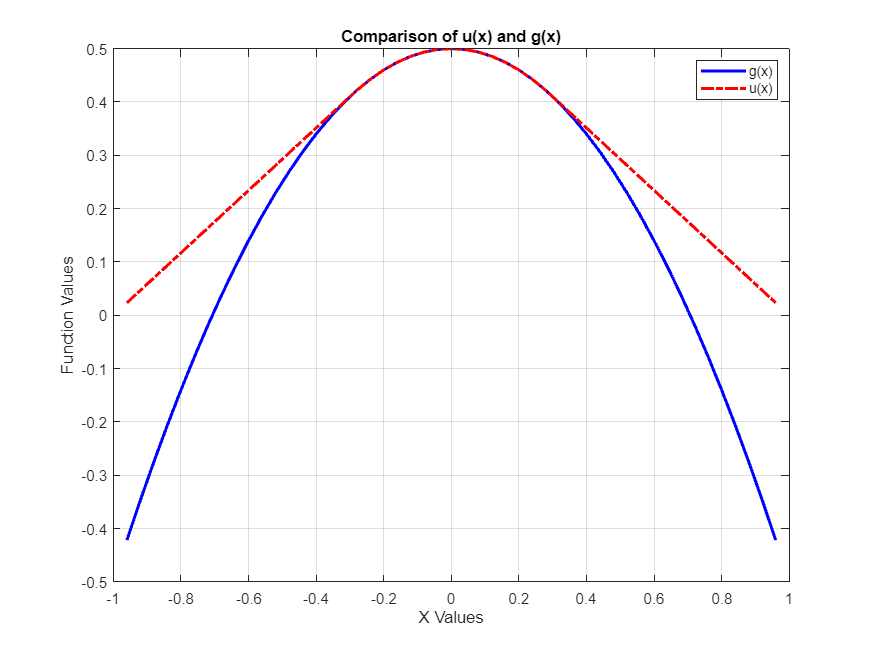

figure('Position', [100, 100, 800, 600]);
plot(xValues, vectorG, 'b', 'LineWidth', 2); % blue curve for vectorG
hold on;
plot(xValues, resultVector, 'r-.', 'LineWidth', 2); % red dashed-dot curve for resultVector

% plot with labels, title, and legend
xlabel('X Values');
ylabel('Function Values');
title('Comparison of u(x) and g(x)');
legend('g(x)', 'u(x)');
grid on; % Displaying a grid for better readability

hold off;

## Function definition

function output = computeFunctionG(inputX)
    output = 0.5 - inputX .* inputX; 
end
